# **Investigate Effect of Cruise Altitude**

% House Keeping
clear
clc
close all

**Basic Parameters**

% Weight
W_crew = 500 * 82.8;                     % Passenger weight + carry-on luggage (kg) % Ref 04 p.45
W_crew = W_crew + (12 + 4) * 79.4;       % Crew weight + carry-on luggage (kg)      % Roskam Part I p.8
W_payload = 500 * 17;                    % Passener checked luggage (kg)            % Ref 04 p.45
W_payload = W_payload + (12 + 4) * 13.6; % Crew checked luggage (kg)                % Roskam Part I p.8

% W_0 = 0;                               % Takeoff gross weight (kg)
% W_f_0 = 0;                             % W_fuel / W_0
% W_e_0 = 0;                             % W_empty weight / W_0

[T_0, c_0, P_0, rho_0] = atmosisa(0);    % Sea-level condition

g = 9.80665;                             % Standard acceleration of gravity (m/s^2)

**Mission Profile**

first cruise

for k = 1 : 100

% since the cruise condition is not specified in given mission
% profile, assume first cruise will be held in cruise-climb to
% maximise the fuel efficiency of the aircraft [Intro to Aero p.117]
h_cruise1 = 28000; % first cruise average altitude (ft)

[T_cruise1, c_cruise1, P_cruise1, rho_cruise1] = atmosisa(convlength(h_cruise1, 'ft','m'));
V_cruise1 = 0.83;

second cruise

h_cruise2 = 18000; % Cruise altitude (ft) for Lost Communications Missed Approach % Ref 5

V_cruise2 = convvel(400, 'kts', 'm/s'); % Assume cruise velocity 400 knots % Ref 5
[T_cruise2, c_cruise2, P_cruise2, rho_cruise2] = atmosisa(convlength(h_cruise2, 'ft','m'));
V_cruise2 = V_cruise2 ./ c_cruise2;

absolute ceiling

absCeiling = convlength(45000,'ft','m'); % Absolute Ceiling

loiter

h_loiter = convlength(5000, 'ft','m'); % Alternate altitude (m)

[T_loiter, c_loiter, P_loiter, rho_loiter] = atmosisa(h_loiter);

**Empirical Airplane Data**

AR = 7 + 0.03 * k; % Aspect ratio

AR_itr(k) = AR;

WR = 5.5;          % S_wet / S_ref         % Raymer p.40
AR_W = AR ./ WR;   % Wetted aspect ratio
K_LD = 15.5;       % For civil jets        % Raymer p.40
LD_max = K_LD .* (AR_W) .^ 0.5; % L/D_max  % Raymer p.41

CD_0 = 0.023;  % Drag ceofficient at zero lift % Boeing 777-300ER
e = 0.85;      % Oswald/span efficiency factor % Boeing 777-300ER
CL_max_L = 2.69;             % Maximum lift coefficient in landing configuration
CL_max_TO = CL_max_L .* 0.8; % Maximum lift coefficient in take-off configuration
CL_max_C = 1.4;              % Maximum lift coefficient in cruise configuration

V_S = convvel(137, 'kts', 'm/s'); % Stall speed at sea level % Boeing 777-300ER
V_A = 1.3 * V_S;                  % Approach speed at sea level % Raymer p.110
V_TO = 1.2 * V_S;                 % Take off velocity (m/s)

**Empirical Engine Data**

NE = 4; % Number of engines

High-bypass Turbofan

C_cruise = 0.5 ./ 3600; % SFC (1/s) % Raymer p.36

Trent 972E-84 

% W_engine = 9630; % Weight of engine (kg)
T_0 = 320300;      % Takeoff thrust (N)
T_0 = T_0 * 1.05;  % Rubber engine
% BPR = 8.5;       % Bypass Ratio % Trent 972E-84 % Ref 17

**Calculate Fuel Fraction **

[W_f_0, W_i] = Wf_W0(h_cruise1, h_cruise2, V_cruise1, V_cruise2, LD_max, C_cruise);

**Calculate Empty Weight Fraction**

% Guess Takeoff gross weight (kg)
W_0 = zeros(2000, 1);

for i = 1:2000
    W_0(i) = 100000 + 750 * i;
end

From regression of historical data (Raymer p.31)


$$\frac{W_E }{W_0 }={\textrm{AW}}_o^C$$


A_Ry = 0.97;  % Constant from jet transport historical data % Raymer p.31
C_Ry = -0.06; % Constant from jet transport historical data % Raymer p.31
W_e_0_Ry = A_Ry .* W_0 .^ C_Ry;

Composite material (Raymer p.51)

W_e_0 = 0.95 * W_e_0_Ry;

**Estimate Takeoff Gross Weight**

% From weight build-up calculations
W_e_0_Cal = 1 - W_f_0 - (W_crew + W_payload) ./ W_0; % Raymer p.34

% Caculate exact value of solution
func_Ry = @(W0) ((W_crew + W_payload) / (1 - W_f_0 - 0.95 .* (A_Ry * W0 ^ C_Ry))) - W0;
W0_initial_guess = 4000000; % Adjust based on expected range

W_0 = fsolve(func_Ry, W0_initial_guess, optimset('Display','off'));
% Output result
W_0_itr(k) = W_0;

**Specific Excess Power (SEP)**


$${\left(\frac{\mathit{\mathbf{T}}}{\mathit{\mathbf{W}}}\right)}_0 =\frac{\alpha }{\beta }\left(\frac{1}{V_{\infty } }\frac{\textrm{dh}}{\textrm{dt}}+\frac{1}{\mathit{\mathbf{g}}}\frac{{\textrm{dV}}_{\infty } }{\textrm{dt}}+\frac{\frac{1}{2}\rho {{\mathit{\mathbf{V}}}_{\infty } }^2 {\mathit{\mathbf{C}}}_{{\mathit{\mathbf{D}}}_0 } }{\frac{\mathit{\mathbf{W}}}{{\mathit{\mathbf{S}}}_{\textrm{ref}} }}+\frac{{\mathit{\mathbf{n}}}^2 \frac{\mathit{\mathbf{W}}}{{\mathit{\mathbf{S}}}_{\textrm{ref}} }}{\frac{1}{2}\rho {{\mathit{\mathbf{V}}}_{\infty } }^2 \pi \textrm{ARe}}\right)$$
 

T0_W0 = @(alpha, beta, dh_dt, dV_dt, W0_Sref, AR, e, V, CD0, n, rho) ...
    alpha ./ beta .* (1 ./ V .* dh_dt + 1 ./ g .* dV_dt + ...
    (0.5 .* rho .* V .^ 2 .* CD0) ./ (alpha .* W0_Sref) + ...
    (alpha .* n .^ 2 .* W0_Sref) ./ (0.5 .* rho .* V .^ 2 .* pi .* AR .* e));

**ICAO Aerodome Reference Code 4E**

Maximum wing span 65 m

W0_S_ICAO = (W_0 .* g) ./ (65 ^ 2 ./ AR);

**Takeoff **(Straight line)

Basic Parameters

sigma = 1;   % Takeoff site ASL
TODA = 2900; % Runway length (m)


$$\textrm{BFL}\;4N_E$$
 

% T0_W0_BFL = (0.297 - 0.019 * NE) .* W0_Sref ./ (sigma * CL_max_TO * TODA);

% Find the crossing point
T0_W0_Selected = (0.297 - 0.019 * NE) .* W0_S_ICAO ./ (sigma * CL_max_TO * TODA);

**1st Cruise **(Curve descend with wing loading)

T0_W0_cruise1 = Constraint_Cruise(h_cruise1, V_cruise1, W0_S_ICAO, W_i(1) * W_i(2), AR, e, CD_0);

**Loiter**

Calculate Indicated Minimum Drag Speed $V_{\textrm{imD}}$ according to $V_{\textrm{maxSAR}} =\frac{V_{i\;\textrm{maxSAR}} }{\sqrt{\sigma }}=\sqrt[4]{3}\frac{V_{\textrm{imD}} }{\sqrt{\sigma }}$ (Intro to Aerospace p.110)

V_imD = (V_cruise1 .* c_cruise1) .* (rho_cruise1 ./ rho_0) .^ 0.5 ./ ((3) .^ 0.25);

Calculate loitering speed, $V=V_{\textrm{mD}} =\frac{V_{\textrm{imD}} }{\sqrt{\sigma }}$

V_mD = V_imD ./ ((rho_loiter ./ rho_0) .^ 0.5);

Calculate ${\left(\frac{T}{W}\right)}_0$

% T0_W0 = @(alpha, beta, dh_dt, dV_dt, W0_Sref, AR, e, V, CD0, n, rho)
T0_W0_loiter = T0_W0(W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5) * W_i(6), T_T0(h_loiter), 0.0, 0.0, W0_S_ICAO, AR, e, V_mD, CD_0, 1, rho_loiter);

W0_S(k) = W0_S_ICAO;
T0_W0_itr(k) = T0_W0_Selected;
LD_cruise_itr(k) = 1 ./ T0_W0_cruise1;
LD_max_itr(k) = 1 ./ T0_W0_loiter;
end

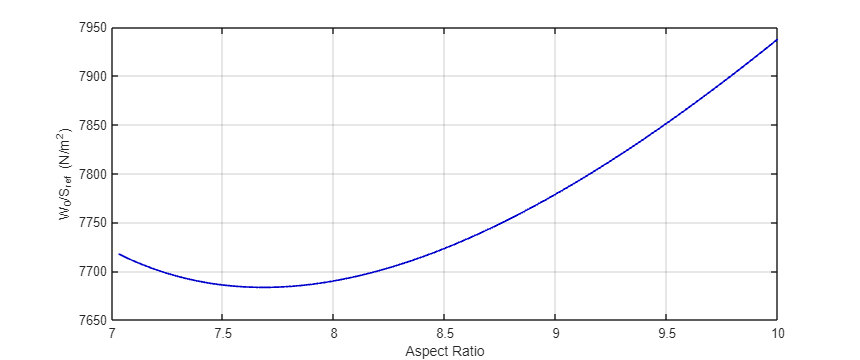

% Plot the comparision diagram

figure(1)

clf;

plot(AR_itr, W0_S, '-', 'Color',  [0/255 0/255 205/255], 'LineWidth', 1.25)

xlabel('Aspect Ratio'); 
ylabel('W_{0}/S_{ref} (N/m^{2})');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis


grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 860 360]); % show plot with larger size 

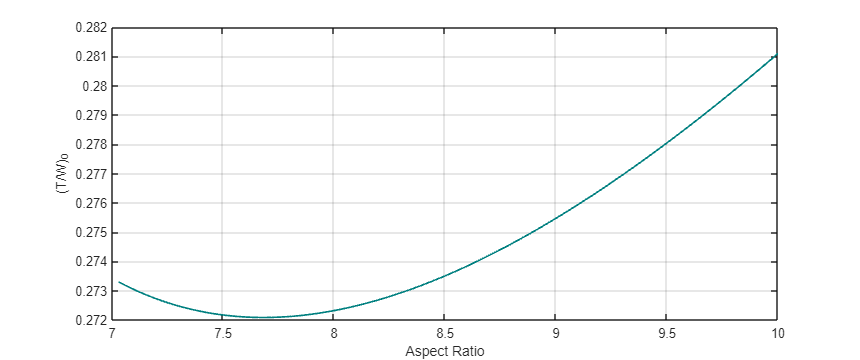

figure(2)

clf;

plot(AR_itr, T0_W0_itr, '-', 'Color',  [0/255 128/255 128/255], 'LineWidth', 1.25)

xlabel('Aspect Ratio'); 
ylabel('(T/W)_{0}');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis


grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 860 360]); % show plot with larger size

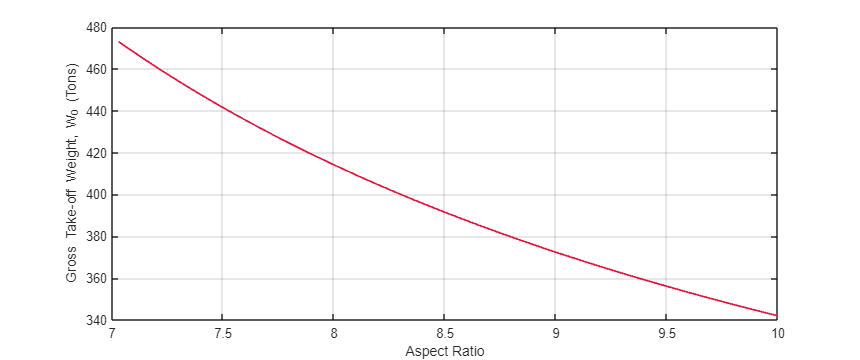

figure(3)

clf;

plot(AR_itr, W_0_itr ./ 1000, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.25);
hold on

xlabel('Aspect Ratio'); 
ylabel('Gross Take-off Weight, W_{0} (Tons)');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis

grid on;                             % set the grid of the graph

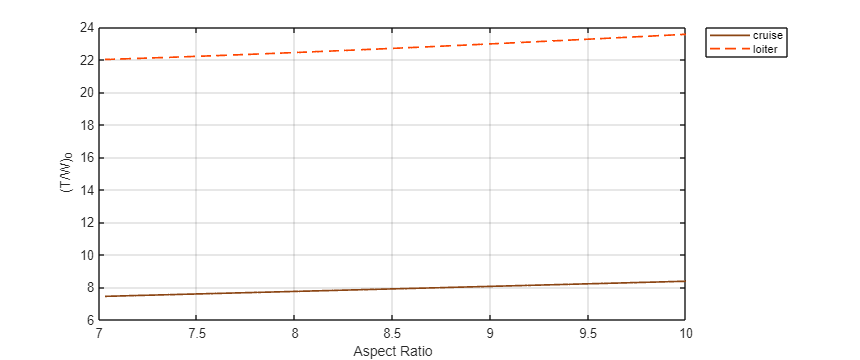

set(gcf, 'Position', [0 0 860 360]); % show plot with larger size 

figure(5)

clf;

plot(AR_itr, LD_cruise_itr, '-', 'Color',  [139/255 69/255 19/255], 'LineWidth', 1.25)
hold on
plot(AR_itr, LD_max_itr, '--', 'Color',  [255/255 69/255 0/255], 'LineWidth', 1.25)
hold off

legend('cruise', 'loiter', ...
       'Location', 'northeastoutside', 'NumColumns', 1, FontSize = 8.5)

xlabel('Aspect Ratio'); 
ylabel('(T/W)_{0}');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis


grid on;                             % set the grid of the graph

set(gcf, 'Position', [0 0 860 360]); % show plot with larger size